# RUN 1st

# LOAD DATA

tic
RegionID = 'TAS1';
% timespan indicates the set of data we need to load. E.g., 2016/12 to 2022/12 
timespan = datetime(2017,12,1):calmonths(1):datetime(2022,12,1);
% PlantName are Wivenhoe, Shoalhaven, Tumut3. Case insensitive, e.g. ShOalHaVen is fine.
CGdata = funcCoalGasdata(timespan, RegionID);
PHSdata = funcPHSdata(timespan, RegionID,'wivenhoe');
VREdata = funcVREdata(timespan, RegionID);
toc

Elapsed time is 2.121273 seconds.


Choose the period that we will do the analysis. Choose the window length for the calculation, for example, opts = 12 means 1-hour length

% hourly MWh
tic
% start date to end date indicates the time frame that we will do the
% analysis. Ofcourse, that time frame must be within the timespan.
start_date = 20180101; end_date = 20221231; opts = 12*2;
calcPHS = funcMWhAndAUD(PHSdata,start_date,end_date,opts);
calcVRE = funcMWhAndAUD(VREdata,start_date,end_date,opts);
calcCG = funcMWhAndAUD(CGdata,start_date,end_date,opts);
totalGL = funcTotalGenLoad(RegionID,timespan,start_date,end_date,opts);
toc

Elapsed time is 1.501293 seconds.


% Daily MWh
tic
calcPHSdaily = funcMWhAndAUD(PHSdata,start_date,end_date,288);
calcVREdaily = funcMWhAndAUD(VREdata,start_date,end_date,288);
calcCGdaily = funcMWhAndAUD(CGdata,start_date,end_date,288);
totalGLdaily = funcTotalGenLoad(RegionID,timespan,start_date,end_date,288);
toc

Elapsed time is 1.183134 seconds.


% Price volatility metrics
tic
[avrRRP, volat1, volat2] = funcAvrRRP(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,opts);
toc

Elapsed time is 0.320380 seconds.


Some other variables that may show us the relationships

tic
solarPcent=calcVRE.SolarMWh./totalGL.genMWh; solarPcentDaily=calcVREdaily.SolarMWh./totalGLdaily.genMWh;
windPcent=calcVRE.WindMWh./totalGL.genMWh; windPcentDaily=calcVREdaily.WindMWh./totalGLdaily.genMWh;
gasPcent=calcCG.GasMWh./totalGL.genMWh; gasPcentDaily=calcCGdaily.GasMWh./totalGLdaily.genMWh;
coalPcent=calcCG.CoalMWh./totalGL.genMWh; coalPcentDaily=calcCGdaily.CoalMWh./totalGLdaily.genMWh;
phsgenPcent=calcPHS.PHSgenMWh./totalGL.genMWh; phsgenPcentDaily=calcPHSdaily.PHSgenMWh./totalGLdaily.genMWh;
phspumpPcent=calcPHS.PHSpumpMWh./totalGL.genMWh; phspumpPcentDaily=calcPHSdaily.PHSpumpMWh./totalGLdaily.genMWh;
toc

Elapsed time is 0.015326 seconds.


# START THE ANALYSIS

Settings

tic
% smoothing window (moving average method)
sw=3; mt='';

## 1. VRE and Coal

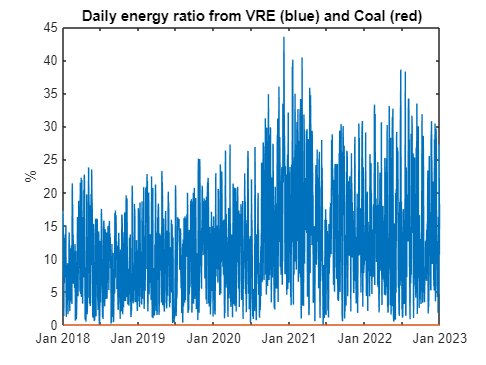

% clf; hold on
v1 = solarPcentDaily+windPcentDaily; 
v2 = coalPcentDaily;
% h = height(v1); d = round(h/5);
% t1 = 1; t2 = d;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d; t2 = d*2;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*2; t2 = d*3;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*3; t2 = d*4;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*4; t2 = h;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% title('More VRE, Less Coal')

clf; 
plot(calcVREdaily.SETTLEMENTDATE,v1*100)
hold on
plot(v2*100)
title('Daily energy ratio from VRE (blue) and Coal (red)'); ylabel("%")

disp('1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


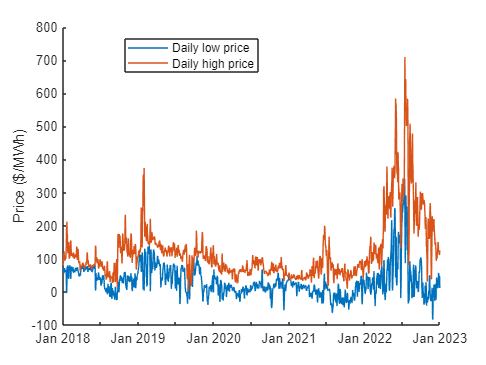

v1 = smooth(volat2.DayMin,sw);
v2 = smooth(volat2.DayMax,sw);

clf; hold on
plot(volat2.SETTLEMENTDATE,v1)
plot(volat2.SETTLEMENTDATE,v2)
ylabel("Price ($/MWh)")
% title("Price spread")
legend("Daily low price","Daily high price")

legend('Position',[0.25978,0.80279,0.27126,0.092992])

## 2. Peaking generators: Gas and PHS - Outlook

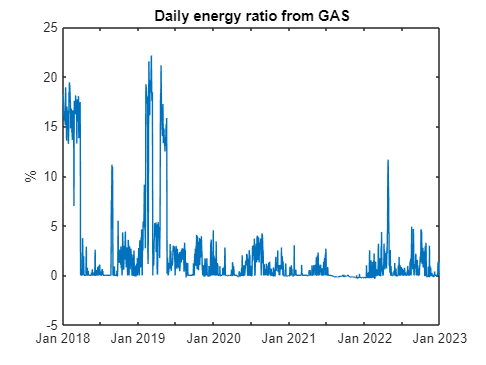

v1 = gasPcentDaily;
v2 = phsgenPcentDaily;
clf; plot(calcVREdaily.SETTLEMENTDATE,v1*100); title('Daily energy ratio from GAS'); ylabel("%")

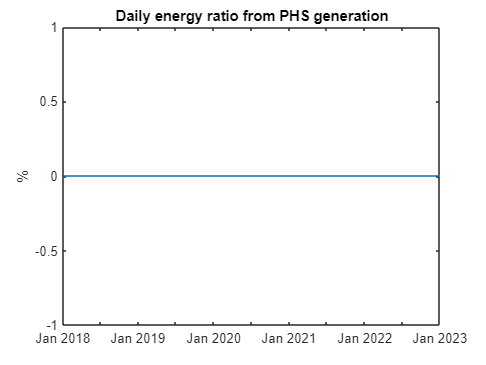

clf; plot(calcVREdaily.SETTLEMENTDATE,v2*100); title('Daily energy ratio from PHS generation'); ylabel("%")

disp('2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


Need more firming capacity. PHS has been used more frequently. *ExtractPHSOperationOutlook* gives: 

### Increase of usage, Revenue - Cost

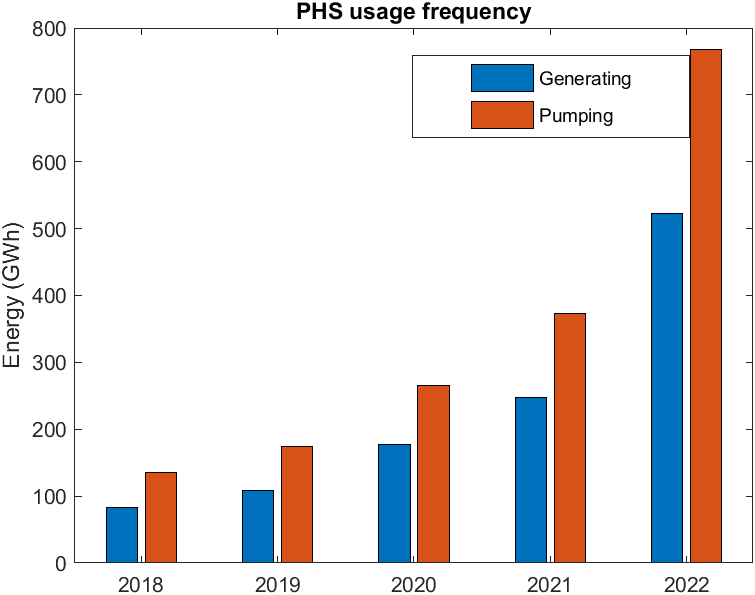 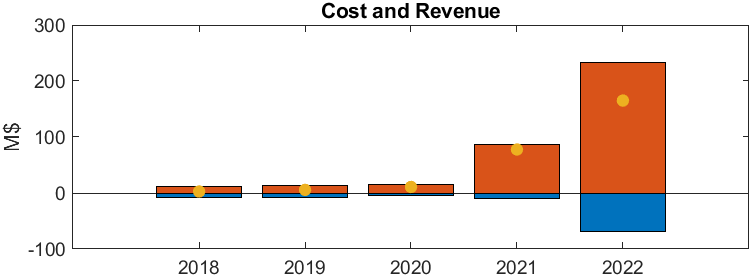

## 3. Natural Gas price raises DayMax

Gas% and average price, hourly. Correlation changes by each time interval, might be dependent on LNG price

v1 = 100*gasPcent; 
v2 = avrRRP.AvrRRP;

clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.4120

scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.4366

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.3055

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.1223

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.4031

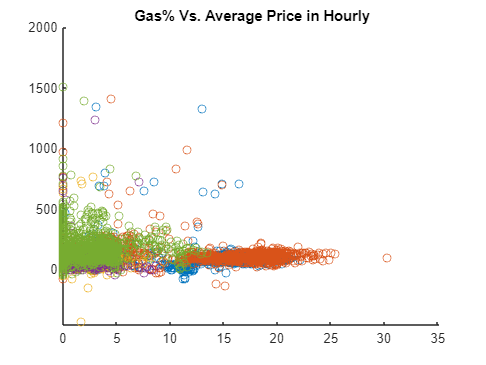

scatter(v1(t1:t2),v2(t1:t2))

% clf;
% corr(v1,v2,"type","Spearman")
% scatter(v1,v2)
title("Gas% Vs. Average Price in Hourly")

xlim([-0.0 35.2])
ylim([-460 2000])

disp('3.1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

3.1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


Effect of GAS% on VOLATILITY (DayMax). Again, correlation changes by each time interval.

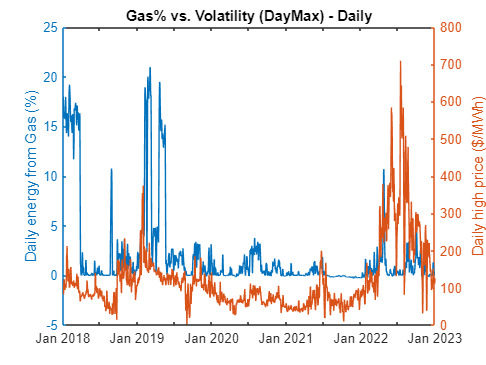

v1 = smooth(gasPcentDaily,sw);
v2 = smooth(volat2.DayMax,sw);

clf; 
yyaxis("left"); plot(volat2.SETTLEMENTDATE,100*v1); ylabel("Daily energy from Gas (%)")
yyaxis("right"); plot(v2); ylabel("Daily high price ($/MWh)")
title('Gas% vs. Volatility (DayMax) - Daily')


clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.5877

scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.6674

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.5664

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.0210

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.2851

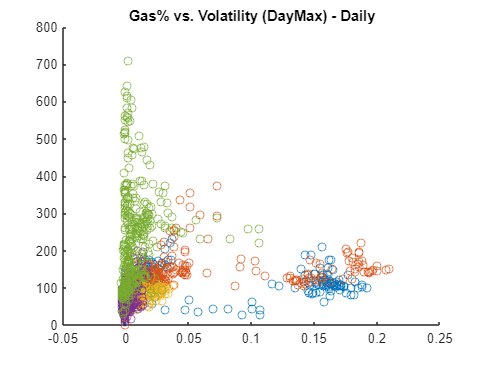

scatter(v1(t1:t2),v2(t1:t2))
title('Gas% vs. Volatility (DayMax) - Daily')

disp('3.2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

3.2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


Effect of LNG PRICE on VOLATILITY: raise daily high price

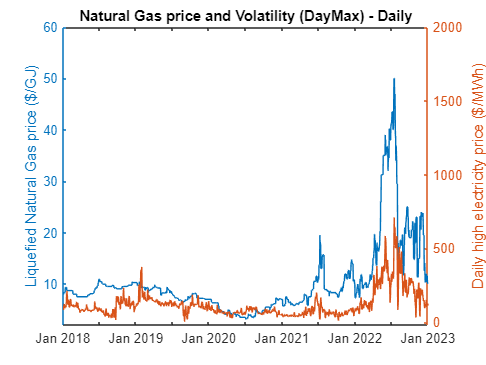

NGasPrice = funcNGasPrice("NGasPrice.csv", [367, Inf]);
% 2,Inf 2017->2022
% 367,Inf 2018->2022

v1 = NGasPrice.NGPrice;
v2 = smooth(volat2.DayMax,sw);
clf; 
yyaxis("left"); plot(NGasPrice.NGDate,v1); ylim([2 60]); ylabel("Liquefied Natural Gas price ($/GJ)")
yyaxis("right"); plot(v2); ylim([-20 2000]); ylabel("Daily high electricity price ($/MWh)")
title('Natural Gas price and Volatility (DayMax) - Daily')

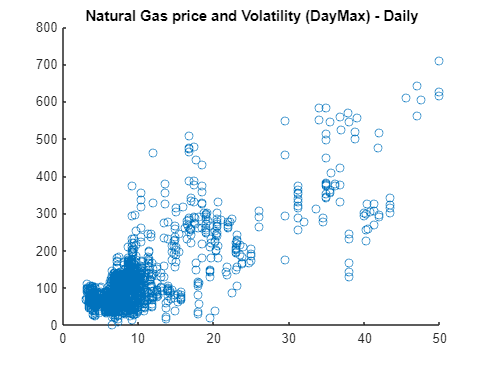


clf;
scatter(v1,v2); title('Natural Gas price and Volatility (DayMax) - Daily')
txt = sprintf('corr = %.2f',corr(v1,v2,type="Spearman"));
text(5,1400,txt);


disp('3.3|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

3.3|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


## 4. VRE lowers DayMin

Moderate correlation

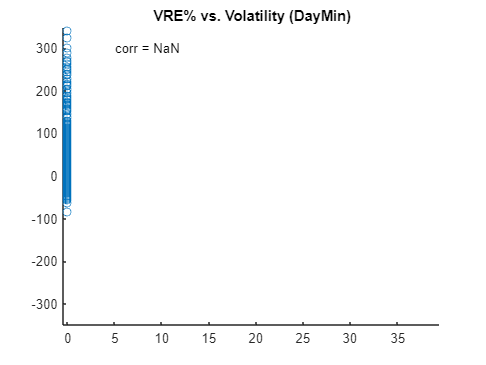

% v1 = 100*(windPcentDaily+solarPcentDaily);
v1 = 100*max(reshape(solarPcent,288/opts,[]))'; %solar daily swing
v2 = smooth(volat2.DayMin,sw);

% clf; hold on
% h = height(v1); d = round(h/5);
% t1 = 1; t2 = d;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d; t2 = d*2;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*2; t2 = d*3;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*3; t2 = d*4;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*4; t2 = h;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))

clf
scatter(v1,v2)
txt = sprintf('corr = %.2f',corr(v1,v2,type="Spearman"));
text(5,300,txt);

title('VRE% vs. Volatility (DayMin)')

xlim([-0.5 39.5])
ylim([-350 350])


% % distance from DayMin to Average
% dayAvr = totalGLdaily.genAUD./totalGLdaily.genMWh;
% dtance = volat2.DayMin-dayAvr;
% v2 = dtance;
% 
% clf
% corr(v1,v2,"type","Spearman")
% scatter(v1,v2)

disp('4|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

4|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


## 5. PHS - price taker

### Gen. price, Pump price

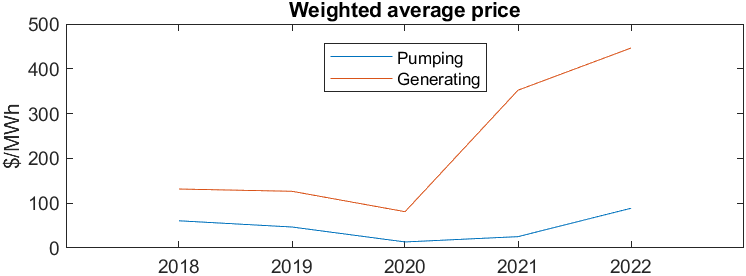

## Explanation

Peaking at sunrise/6am and sunset/6pm

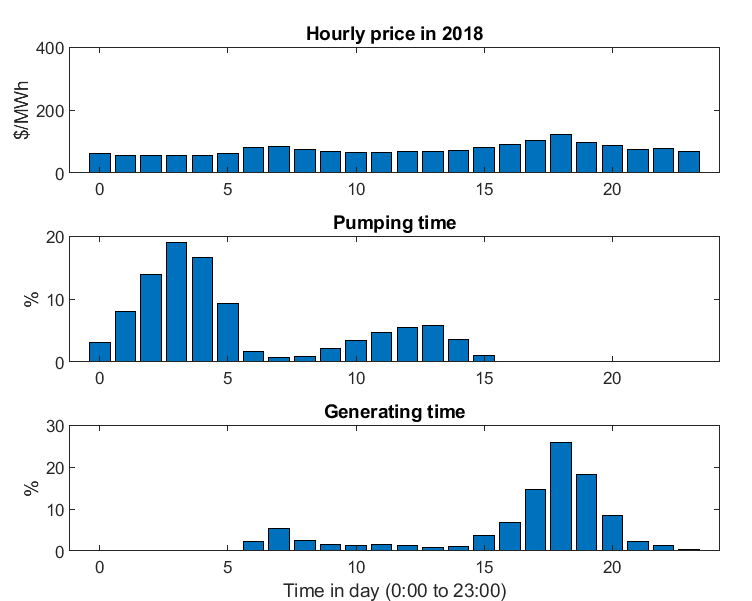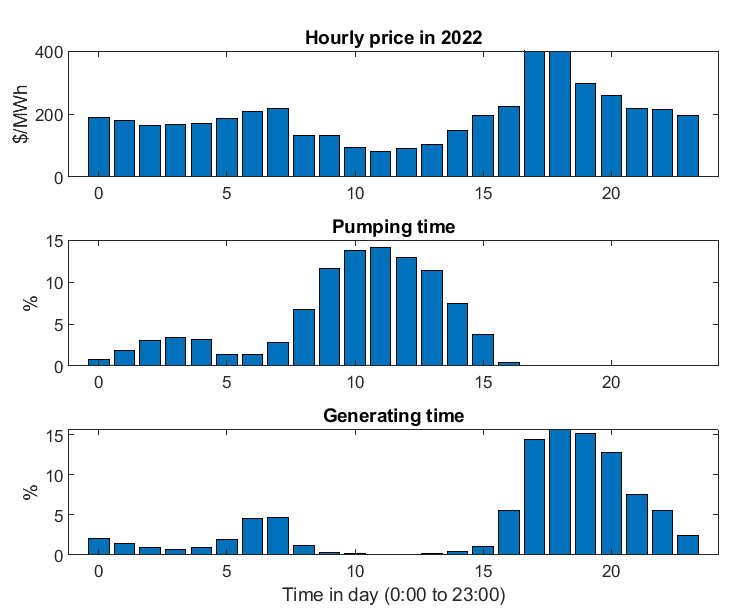

v1 = smooth(calcPHSdaily.PHSgenAUD-calcPHSdaily.PHSpumpAUD,sw);
v2 = smooth(volat2.Spread,sw);

clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = NaN

scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = NaN

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = NaN

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = NaN

scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = NaN

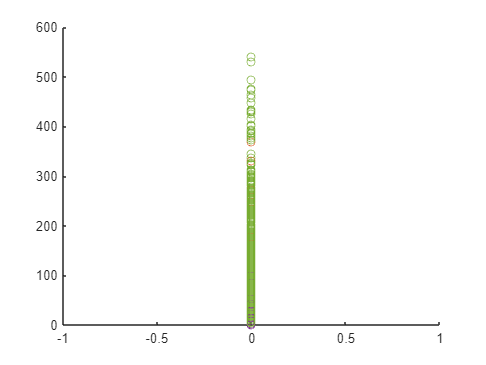

scatter(v1(t1:t2),v2(t1:t2))


% clf; hold on
% yyaxis("left");plot(v1);
% yyaxis("right");plot(v2)

disp('5|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

5|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


% https://au.mathworks.com/help/curvefit/smoothing-data.html

% Pearson correlation coefficient measures the linear relationship (linear assumption)
% Spearman correlation coefficient measures the monotonic relationship (monotonic assumption), 
% which means that as one variable increases, the other variable either increases or decreases in a consistent manner

toc

Elapsed time is 13.941577 seconds.
